Sound analysis

[x, fs] = audioread("block hit.wav");

x = x(:, 1);

n = length(x);
t = (0:n-1)/fs;
n/fs

ans = 0.8700

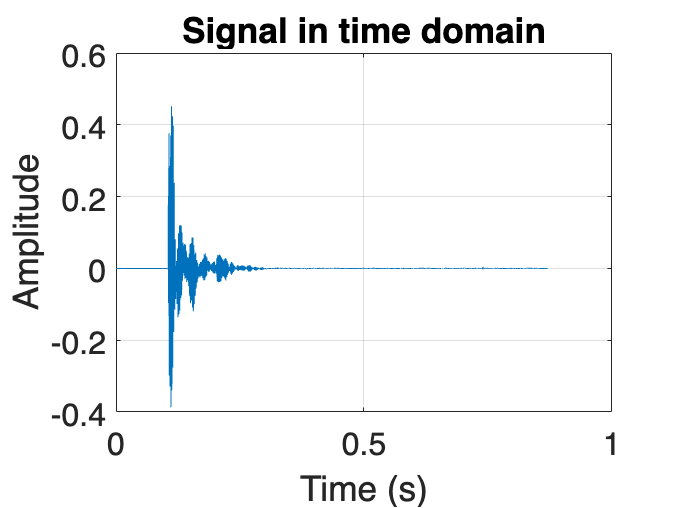

%plot time domain signal
plot(t, x)
grid on
set(gca, 'FontName', 'Helvetica', 'fontSize', 16)
xlabel('Time (s)')
ylabel('Amplitude')
title('Signal in time domain')

%stats information
maxValue = max(x)

maxValue = 0.4514

minValue = min(x)

minValue = -0.3865

meanValue = mean(x)

meanValue = -4.1261e-05

stdValue = std(x)

stdValue = 0.0285

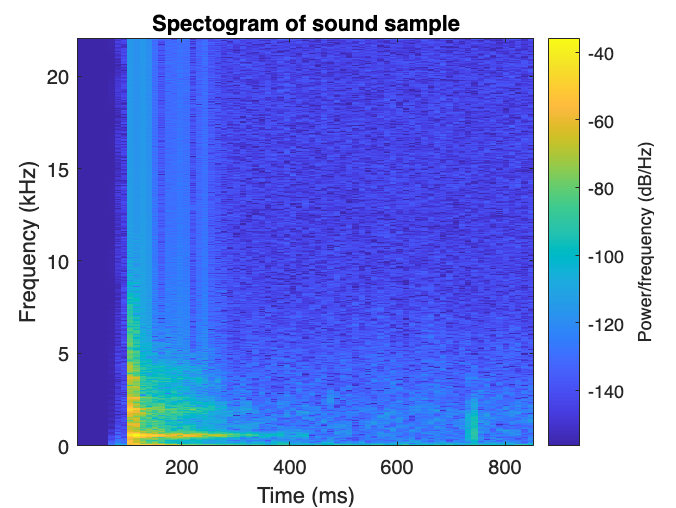

spectrogram(x, 1024, 512, 1024, fs, 'yaxis')
title('Spectogram of sound sample')

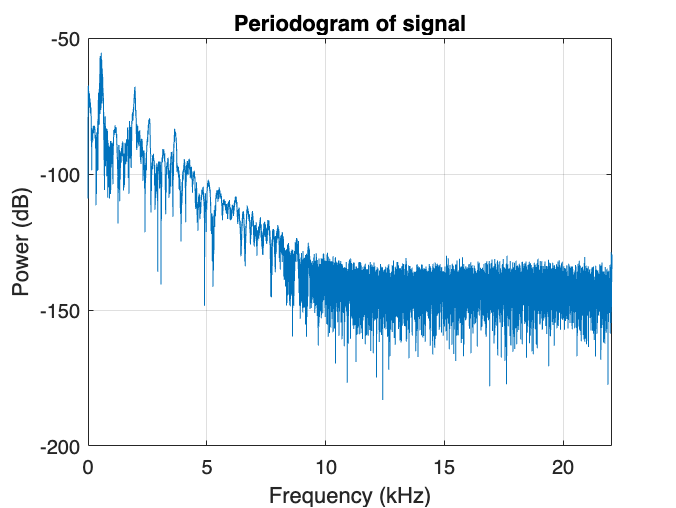

%periodogram plot
w = hanning(n, 'periodic');
periodogram(x, w, n, fs, 'power')
title('Periodogram of signal')

[logx, logf] = periodogram(x, w, n, fs, 'power');
logx = 20*log10(sqrt(logx)*sqrt(2));

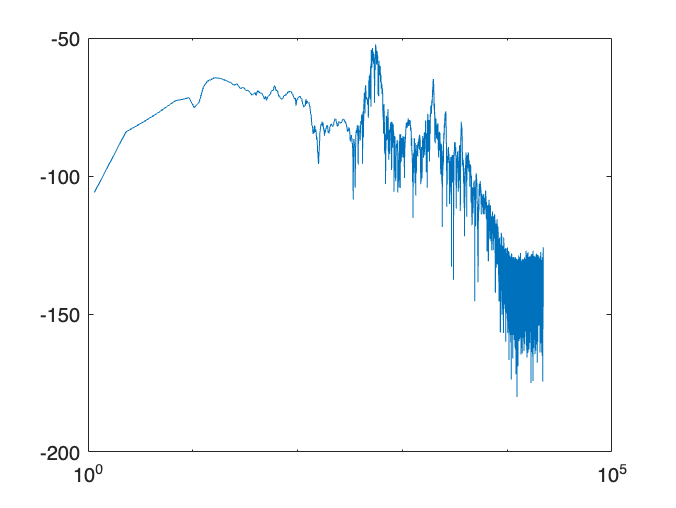

semilogx(logf, logx)

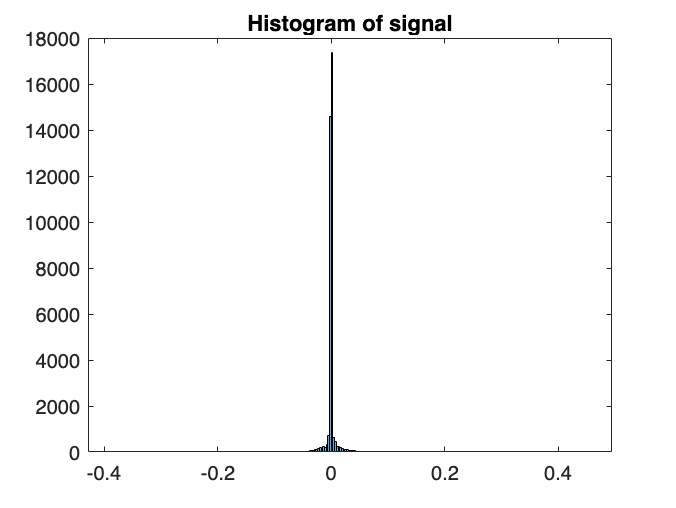

%plot histogram
histogram(x)
title('Histogram of signal')